## 前進動作における真値とオドメトリの比較

csvFilePath = 'forward_roomba_data.csv';
dataMatrix = readmatrix(csvFilePath);

csvFilePath2 = 'forward_motioncap_data.csv';
dataMatrix4 = readmatrix(csvFilePath2);

time = dataMatrix(:,1)/1000;  % 時間 [s]
time = time - time(1);
theta = dataMatrix(:,4);     % theta
vel = dataMatrix(:,5);    
omega = dataMatrix(:,6);

enc_l = dataMatrix(:,7);
enc_r = dataMatrix(:,8);

x = dataMatrix(:,2);     % x座標
y = dataMatrix(:,3);     % y座標


true_x = dataMatrix4(:,2);
true_y = dataMatrix4(:,3);
true_y = true_y - true_y(1,1);

x(162,1)-true_x(1507,1)

ans = 0.0062

y(162,1)-true_y(1507,1)

ans = 0.1832

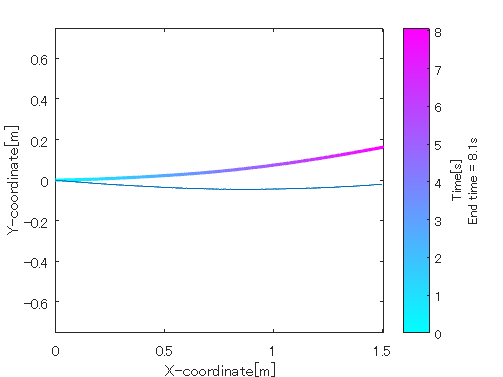


% プロット設定
figure;
ax = gca;
hold(ax, 'on');
box on;

colormap('cool');
c = colormap;
color_steps = size(c, 1);

%プロット
for i = 1:length(time)-1
    color_index = round((i-1)/(length(time)-1) * (color_steps-1)) + 1;
    line_color = c(color_index, :);
    
    plot(ax, [x(i), x(i+1)], [y(i), y(i+1)], 'Color', line_color, 'LineWidth', 2);
end

plot(ax, true_x,true_y)

% 軸ラベルなどの設定
ylim(ax,[-0.75,0.75]);
xlabel(ax, 'X-coordinate[m]');
ylabel(ax, 'Y-coordinate[m]');

% カラーバーの表示
clim(ax, [min(time), max(time)]);
hcb = colorbar;
xlabel(hcb, {'Time[s]',['End time = ',num2str(round(max(time),1)),'s']});


hold(ax, 'off');

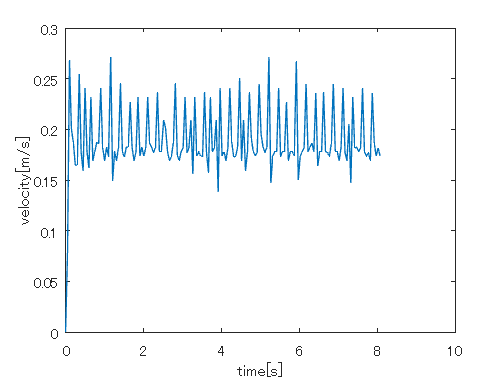


plot(time,vel)
xlabel(ax, 'time[s]');
ylabel(ax, 'velocity[m/s]');

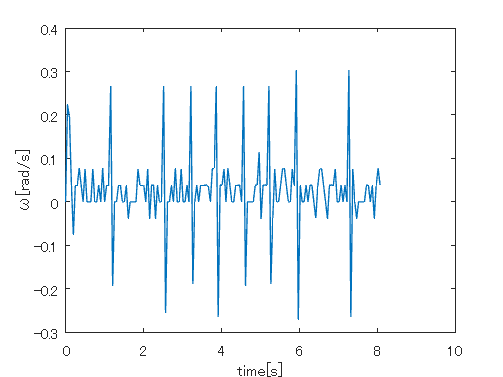

plot(time,omega)
xlabel(ax, 'time[s]');
ylabel(ax, 'ω[rad/s]');

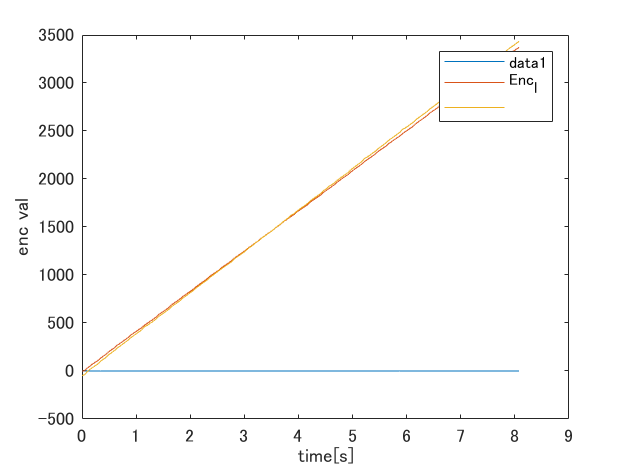


hold('on');
plot(time,enc_l,'DisplayName','Enc_l');
plot(time,enc_r,'DisplayName','Enc_r');
legend
xlabel('time[s]');
ylabel('enc val');
hold('off');

time = dataMatrix(:,1)/1000;  % 時間 [s]
time = time - time(1);
theta = dataMatrix(:,4);     % theta

true_time = dataMatrix4(:,1);
true_time(1:569,:)=[];
true_time = true_time - true_time(1,1);
%true_time = true_time - -0.027;
true_theta = dataMatrix4(:,4);
true_theta(1:569,:)=[]

true_theta =     0.0079
    0.0079
    0.0076
    0.0078
    0.0083
    0.0088
    0.0098
    0.0106
    0.0116
    0.0121



theta(end,1)-true_theta(end,1)

ans = 0.0379

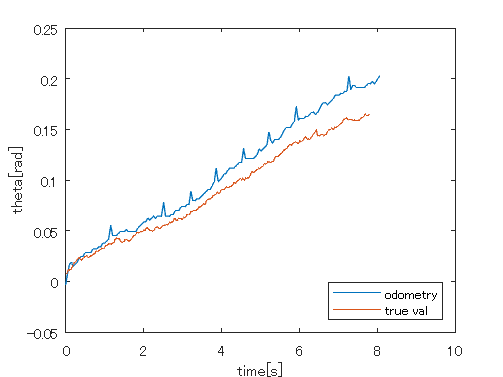


% プロット設定
figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time,theta,'DisplayName','odometry')
plot(ax, true_time,true_theta,'DisplayName','true val')
legend('Location','southeast');

% 軸ラベルなどの設定
xlabel(ax, 'time[s]');
ylabel(ax, 'theta[rad]');
hold(ax, 'off');

## 旋回動作における真値とオドメトリの比較

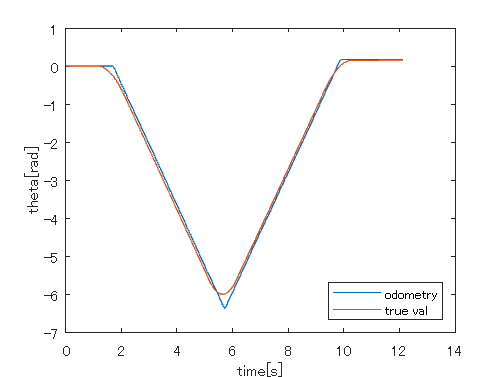

csvFilePath3 = 'turn_roomba_data.csv';
dataMatrix3 = readmatrix(csvFilePath3);

csvFilePath4 = 'turn_motioncap_data.csv';
dataMatrix4 = readmatrix(csvFilePath4);

time = dataMatrix3(:,1)/1000;  % 時間 [s]
time = time - time(1);
theta = dataMatrix3(:,4);     % theta
vel = dataMatrix3(:,5);
omega = dataMatrix3(:,6);
true_time = dataMatrix4(:,1);
true_time = true_time - true_time(1,1);
true_time = true_time - -0.027;
true_theta = dataMatrix4(:,4);

% プロット設定
figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time,theta,'DisplayName','odometry')
plot(ax, true_time,true_theta,'DisplayName','true val')
legend('Location','southeast');

% 軸ラベルなどの設定
xlabel(ax, 'time[s]');
ylabel(ax, 'theta[rad]');
hold(ax, 'off');

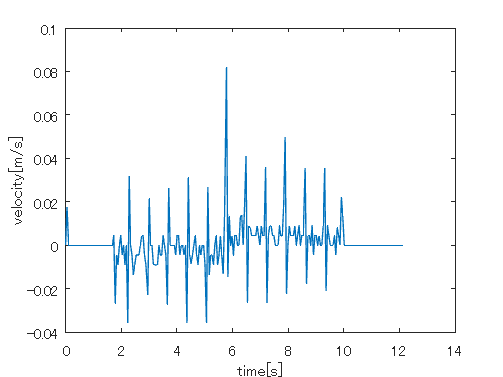


plot(time,vel)
xlabel(ax, 'time[s]');
ylabel(ax, 'velocity[m/s]');

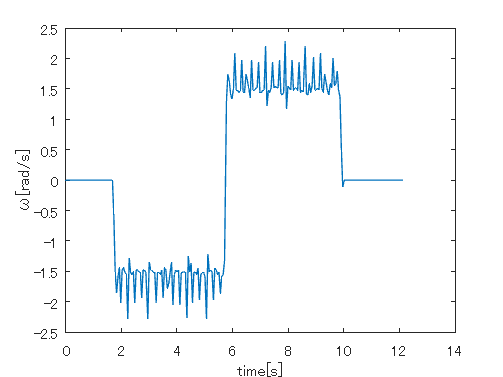

plot(time,omega)
xlabel(ax, 'time[s]');
ylabel(ax, 'ω[rad/s]');

csvFilePath = 'turn_roomba_data.csv';
dataMatrix = readmatrix(csvFilePath);

csvFilePath2 = 'turn_motioncap_data.csv';
dataMatrix4 = readmatrix(csvFilePath2);

time = dataMatrix(:,1)/1000;  % 時間 [s]
time = time - time(1);
theta = dataMatrix(:,4);     % theta
x = dataMatrix(:,2);     % x座標
y = dataMatrix(:,3);     % y座標


true_x = dataMatrix4(:,2);
true_y = dataMatrix4(:,3);
true_x = true_x - true_x(1,1);
true_y = true_y - true_y(1,1);


x(241,1)-true_x(122,1)

ans = 0.0104

y(241,1)-true_y(122,1)

ans = 0.0035

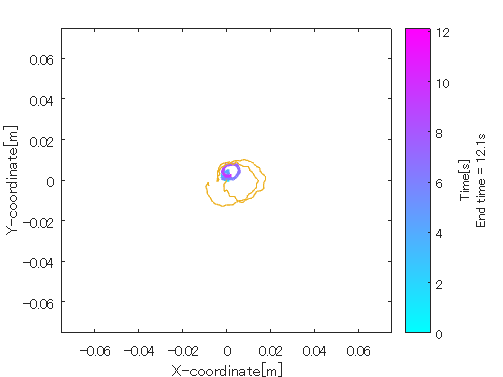


% プロット設定
figure;
ax = gca;
hold(ax, 'on');
box on;

colormap('cool');
c = colormap;
color_steps = size(c, 1);

%プロット
for i = 1:length(time)-1
    color_index = round((i-1)/(length(time)-1) * (color_steps-1)) + 1;
    line_color = c(color_index, :);
    
    plot(ax, [x(i), x(i+1)], [y(i), y(i+1)], 'Color', line_color, 'LineWidth', 2);
end

plot(ax, true_x,true_y)

% 軸ラベルなどの設定
xlim(ax,[-0.075,0.075]);
ylim(ax,[-0.075,0.075]);
xlabel(ax, 'X-coordinate[m]');
ylabel(ax, 'Y-coordinate[m]');

% カラーバーの表示
clim(ax, [min(time), max(time)]);
hcb = colorbar;
xlabel(hcb, {'Time[s]',['End time = ',num2str(round(max(time),1)),'s']});

hold(ax, 'off');

time = dataMatrix(:,1)/1000;  % 時間 [s]
time = time - time(1);
theta = dataMatrix(:,4);     % theta

true_time = dataMatrix4(:,1);
%true_time(1:569,:)=[];
true_time = true_time - true_time(1,1);
true_time = true_time - -0.027;
true_theta = dataMatrix4(:,4);
%true_theta(1:569,:)=[]
% プロット設定
figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time,theta,'DisplayName','odometry')
plot(ax, true_time,true_theta,'DisplayName','true val')
legend('Location','southeast');

% 軸ラベルなどの設定
xlabel(ax, 'time[s]');
ylabel(ax, 'theta[rad]');
hold(ax, 'off');